# **CS/SE 4X03 Tutorial 2**

## **Quick Note - Vectorization**

x = 1:10;
y = (1:10)';

sum = 0;

% We can loop over the vectors
for i = 1:10
    sum = x(i)*y(i) + sum;
end

sum

sum = 385

% Or vectorize the indices and perform without the loop
i = 1:10;
x(i)*y(i)

ans = 385

## Exercise 1 - 1.2.8

**Q:** Determine how many terms are needed to compute $e$ correctly to 15 digits using the Taylor series for $e^x$.

**A: **To answer this, we will have to examine the Taylor series and error term


$$\begin{array}{ll}
f(x)&=\sum_{i=0}^{\infty}\frac{f^{(i)}(0)}{i!}x^i \\
  &=\sum_{i=0}^{n-1}\frac{f^{(i)}(0)}{i!}x^i+\frac{f^{(n)}(t)}{n!}x^n, \quad t \text{ between 0 and $x$}.
\end{array}$$


Here $f(x) = e^x$. Then 


$$e^x=\sum_{i=0}^{n-1}\frac{1}{i!}x^i+\frac{e^t}{n!}x^n .$$


For $x>0$, the maximum error is given by


$$E(n,x) = \frac{e^x}{n!}x^n.$$


We need for find the smallest $$n$$ for which $E(n,x) \le 10^{-15}$. 

clear;
% E(n,x)
E = @(n,x)(exp(x)/factorial(n))*x^n;

x=1; tol = 1e-15;
% A brute force approach is to check n until E(n,x)<1e-15
n=1;
while (1)
     if E(n,x) <= tol
        fprintf("E(%d)= %e\n", n, E(n,x));
        break;
    end
    n=n+1;
end

E(18)= 4.245741e-16


%To check our calculation, we compute the sum with n-1 terms. 
N = [0:n-1];
expSum = @(x,n) sum( x.^N./factorial(N));
error = expSum(x,n) - exp(x);
fprintf("expSum(%g,%d) - exp(%g)=%.2e\n",  x, n, x, error);  

expSum(1,18) - exp(1)=0.00e+00



%For 1e-15, this error is 0. Use vpa to obtain more accurate error
error = expSum(x,n) - exp(vpa(x));
fprintf("expSum(%g,%d) - exp(%g)=%.2e\n",  x, n, x, double(error)); 

expSum(1,18) - exp(1)=3.00e-16


## Exercise 2 - 1.2.9

**Q: **Following 1.2.8, if $x<0$, what are the signs of the terms in the series? Why does using $e^{-x}=1/e^x$ reduce the error?   

We have  $\begin{array}{ll}
f(x)&=\sum_{i=0}^{\infty}(-1)^n\frac{f^{(i)}(0)}{i!}x^i \\
  
\end{array}$.

%Take x = -10, n = 20;
x = -10; n = 20;
error = expSum(x,n)-exp(x);
fprintf("expSum(%g,%d) - exp(%g)=%.2e\n",  x, n, x, error);  

expSum(-10,20) - exp(-10)=-1.02e+02


%Now compute using e^(-x) = 1/e^x
error = 1/expSum(-x,n)-exp(x);
fprintf("1/expSum(%g,%d) - exp(%g)=%.2e\n",  x, n, x, error);  

1/expSum(-10,20) - exp(-10)=6.58e-07


**Moral:** **cancellation** errors need to be treated carefully!

## Exercise 3 - 1.2.25

**Q: **Find range of $x$ (single interval that includes 0), that when using $x$ to approximate $sin(x)$, the *relative* error is below $5\times10^{-15}$.

From the Taylor series expansion of $\sin \left(x\right)=x-\frac{x^3 }{6\;\;}+O\left(x^5 \right)$, $\left|\sin \left(x\right)-x\right|=x^3 +O\left(x^5 \right)$ and

        
$$\begin{array}{ll}
\text{RE}(x) &= \left|\frac{\sin(x) - x}{\sin(x)}\right| = \left| 
\frac{-x^3/6}{\sin(x)}\right|+O(x^5)\\
&\approx  \left| 
\frac{-x^3/6}{x-x^3/6}\right|\\
& = 
\frac{x^2/6}{1-x^2/6}\\
&\approx x^2/6 \quad \text{ for $x$\   small}.
\end{array}$$


From $$x^2/6 \le 5\times 10^{-15}$$, 

$$|x| \le \sqrt{30\times 10^{-15}$$.

To check this calculation, 

tol = 1e-15;
bound = sqrt(6*tol);
x = bound;
%Use vpa because of the cancellations in sin(x)-x, the result may not be
%accurate
xvpa = vpa(x);
RE = @(x) abs( (sin(x)-x)./sin(x) );
fprintf("RE(%g)=%e\n", x, double(RE(xvpa)));

RE(7.74597e-08)=1.000000e-15


%try smaller x
x = .99*bound;
fprintf("RE(%g)=%e\n", x, double(RE(vpa(x))));

RE(7.66851e-08)=9.801000e-16


%try larger x
x = 1.01*bound;
x = vpa(x);
fprintf("RE(%g)=%e\n", x, double(RE(vpa(x))));

RE(7.82343e-08)=1.020100e-15


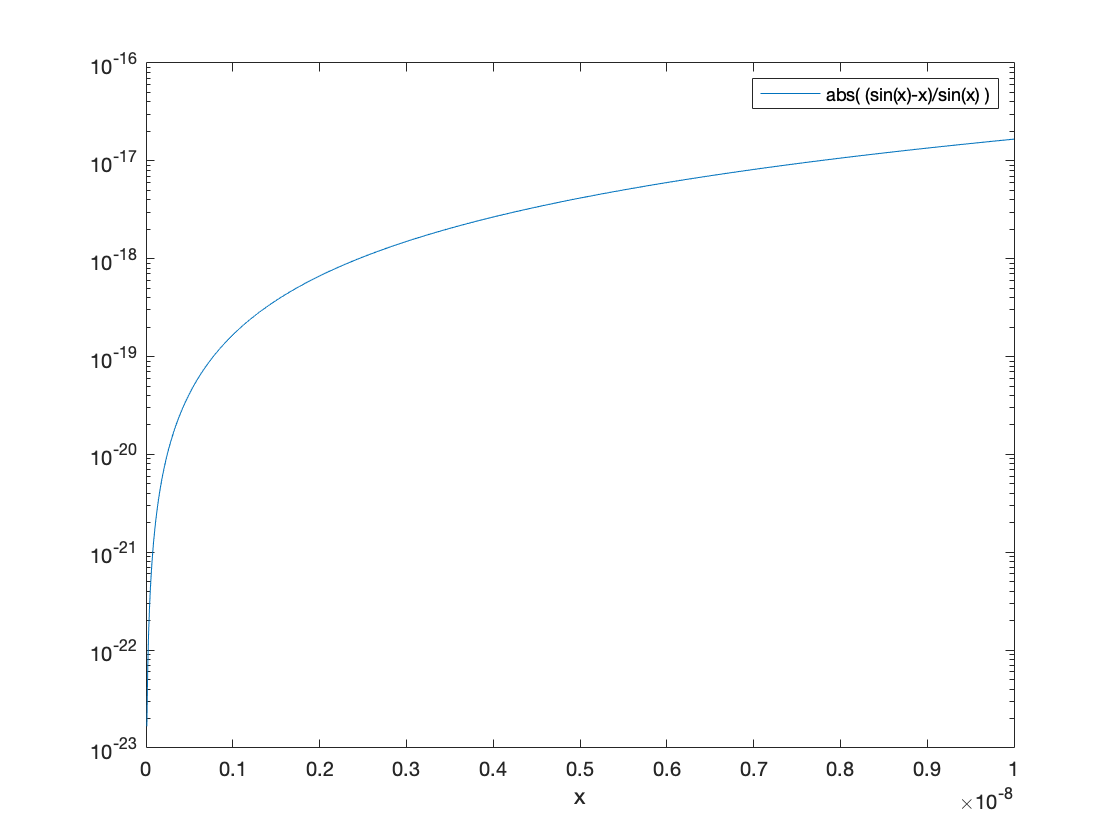

%We can plot the relative error
x = linspace(0, 1e-8,1000);
%Use semilogy, as  plot will produce a line.
semilogy(x,RE(vpa(x)));
xlabel('x'); legend('abs( (sin(x)-x)/sin(x) )')

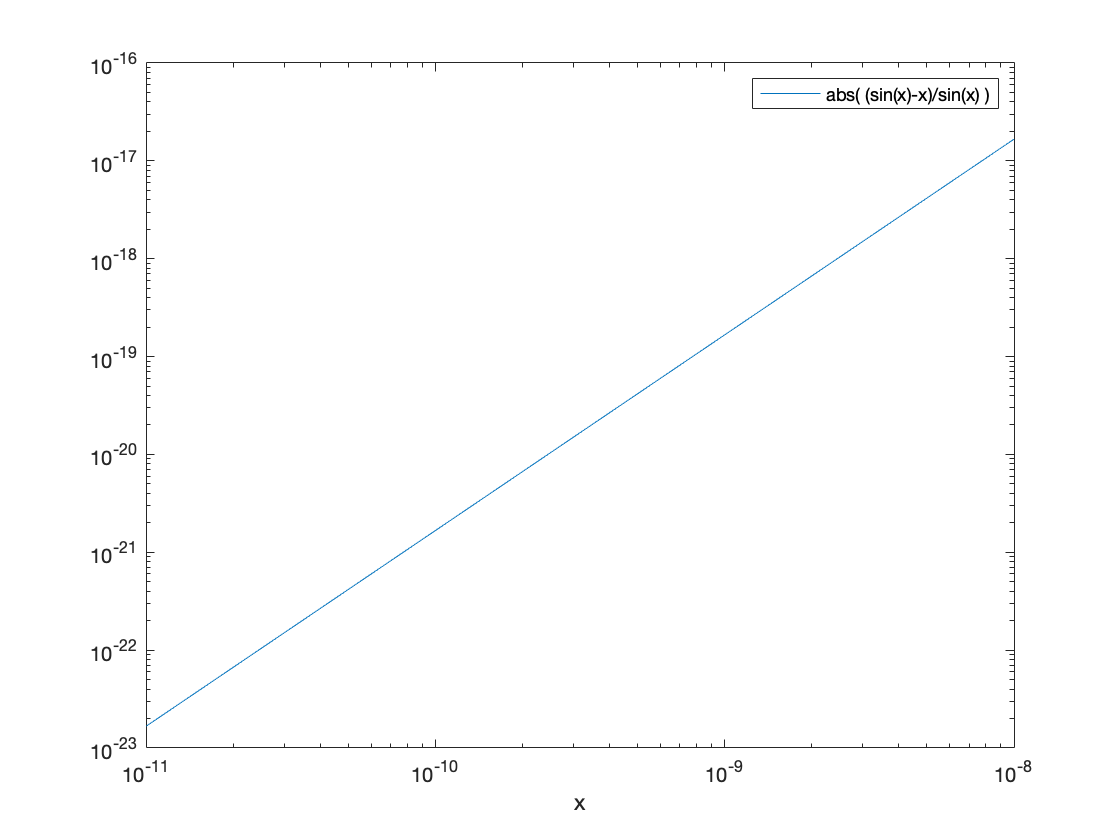

%now plot on loglog scale 
loglog(x,RE(vpa(x)));
xlabel('x'); legend('abs( (sin(x)-x)/sin(x) )')

### Brief(ish) Aside - O(x) Notation ("Big O" Notation)

The big-O notation is a convenient shorthand to examine the crucial components of an infinite series, without having to abstractly truncate the infinite series into an approximation.

As h converges to zero, the error term, $E_{n+1}$ also converges to zero with essentially the same rapidity with which $h^{n+1}$ converges to zero. For large $n$, this is quite rapid. To express this qualitative fact, we write:


$$E_{n+1} = O(h^{n+1})$$


**Big O **notation is shorthand for the inequality:

$|E_{n+1}|\leq C|h|^{n+1}$ where is $C$ a constant.

Roughly speaking, $E_{n+1}=O(h^{n+1})$ means that the behavior of $E_{n+1}$ is similar to the much simpler expression $h^{n+1}$

## Exercise 4 - 1.3.18

### Reminder - [Rounding to Nearest, Ties to Even](https://en.wikipedia.org/wiki/IEEE_754#Rounding_rules)

IEEE-754 specifies rounding to nearest, where ties are resolved by rounding to the even floating-point number (in binary, the one whose least significant digit is **0**).

**Consider the decimal case:** Suppose we wish to round to three significant digits in a decimal system. 

Take 2.315. It is midway between 2.31 and 2.32. We round to the number with the even least significant digit: 2.32

Take 2.325. It is midway between 2.32 and 2.33. We round to the number with the even least significant digit: 2.32

**Q:** In a 5-digit decimal machine with rounding to nearest, what is the $x$ with $\text{fl}(1.0000+x)=1.0000$?

**Hint:** Consider how a number that is either greater or less than 1 will be represented.

**A: **What range of numbers round to 1.0000, given 5 digits of precision and rounding to nearest?

The number before 1.0000 is $9.9999\times 10^{-1} = 0.99999$. The number after 1.0000 is $1.0001 \times 10^0 = 1.0001$. The midpoints between these values are $0.999995$ and $1.00005$. Since the least significant digit is $0$, we know include these midpoints in our range giving:


$$(1+x)\in [0.999995,1.00005]$$


Solving for $x$ gives our answer


$$x\in [-0.000005, 0.00005]$$


And so if $x\in[-0.000005, 0.00005]$, $fl(1+x)=1.0000$.

## **Exercise 5 - 1.3.24**

**Q: **Suppose a 15-digit machine with **chopping rounding**, what is the upperbound for a relative error?

**Note**: chopping rounding is also called round to zero.

**A: **


$$\begin{array}{ll}
x &= \pm d_0.d_1\cdots d_{14}d_{15}d_{16}\cdots\times 10^{e}\quad d_0\neq0\\
\widehat{x}&=\pm d_0.d_1\cdots d_{14}\times 10^e
\end{array}$$


Looking at the absolute error $|x-\widehat{x}|$:


$$\begin{array}{ll}
\left|x - \widehat{x}\right|&=0.0\cdots 0d_{15}d_{16}\cdots\times 10^e \\
&= d_{15}d_{16}\cdots\times 10^{e-15}\\
&\leq 9.9\cdots9\times 10^{e-15} < 10^{e-14}
\end{array}$$


Because we are employing chopping rounding we know:


$$|x| = 1.0...0...\times10^e\geq 1.0...0\times10^e=10^e
% Ned said 0..., but shouldn't it just be 0, since 1.0...0...x10^e > 1.0...0x10^e, which is what we are chopping to?$$


And now computing our bounds on the relative error:


$$\frac{|x-\widehat{x}|}{|x|} < \frac{10^{e-14}}{10^e} = 10^{-14}$$


## Exericse 6 - 1.4.24

**Q: **Indicate how the following formulas may be useful for arranging computations to avoid loss of significant digits.

- 
$$\sin x-\sin y=2\sin(0.5(x-y))\cos(0.5(x+y))$$


- 
$$\log x - \log y=\log(x/y)$$


- 
$$e^{x-y} = e^x/e^y$$


- 
$$1-\cos x=2\sin^2(x/2)$$


- 
$$\arctan x-\arctan y=\arctan\left(\frac{x-y}{1+xy}\right)$$


**Recall**: When values are close together, **cancellation** **errors** can result in loss of accuracy. 

If we:

- **add **two numbers of **opposite sign** 

- **subtract** two numbers of the **same sign**.

**A:**

- When $x\approx y$ then $\sin x \approx \sin y$ The effect of cancellations on $x-y$ will be less compared to $\sin x - \sin y$ which have their own errors.

- When $x\approx y$ then $\log x\approx\log y$. This can lead to cancellations in $\log x - \log y$ which will not occur in $\log\frac{x}{y}$

- When $x\approx$ y there may be cancellations in the evaluation of $x-y$. There are no cancellations in $\frac{e^x}{e^y}$.

- When $x\approx k\pi,\,k\in\mathbb{Z}$ we have $1\approx\cos x$. There are no cancellations in $2\sin^2\left(\frac{x}{2}\right)$.

- When $x\approx y$ we have that $\text{atan}x\approx\text{atan}y$. Similar to **1.**, we can't remove the chance for a cacellation, but $\text{atan}x$ and $\text{atan}y$ will introduce additional error.

Consider the following, using the relation in **5.**

Here, `x` and `y` are machine numbers. Assume they don't have errors. The subtraction x-y may not even have a roundoff error. So x-y is exact. We have digits cancelling, but we assume all are correct in x and y, that they do not contain roundoff.

$\text{atan}$ on the other hand will have at least one (binary) digit wrong.

x = 1.795199901137063;
y = x*(1+1e-12);

f1 = @(x,y) atan(x)-atan(y);
f2 = @(x,y) atan( (x-y)/(1+x*y) );
format short;
 
errror_f1 = double(f1(x,y) - f2(vpa(x), vpa(y)))

errror_f1 = -2.9039e-17

format short;
errror_f2 = double(f2(x,y) - f2(vpa(x),vpa(y)))

errror_f2 = 4.0409e-30

I'll leave testing the rest to the reader as an exercise

**Moral: **When we have two numbers which are close in value, it is important to consider whether a **cancellation error **will occur. The relations above provide alternative means of evaluating to either remove the possibility of cancellations, or to reduce their effect.

## Exercise 7 - 1.4.26

**Q: ** Find ways to compute these functions without serious loss of significant digits.

- 
$$e^x-\sin x-\cos x$$


- 
$$\ln(x)-1$$


- 
$$\log(x)-\log(1/x)$$


- 
$$x^{-2}(\sin x - e^x + 1)$$


- 
$$x-\text{arctanh} x$$


**A: **The idea here is to look for an alternative form that excludes cancellation errors.This often will involve a Taylor series expansion, although that will not necessarily always provide a better form.

 Some of the relations from Exercise 6 may be useful here. 

- Write out as a TS

- Recall: $\log x - \log y = \log(x/y)$

- Recall: $\log x = - \log(1/x)$

- Write out as a TS

- Write out as a TS

I feel like just running through all the examples for the reader is not particularly beneficial other than as a reference for dealing with individual cases. I have decided to provide one worked Taylor series solution (for Equation 1) and one equation substitution solution (for Equation 2). I strongly encourage you to try to do 3-5 yourself, keeping in mind the relation provided in the hint, and to get practice with Taylor series and the big-O notation. If you are unsure of your TS solution, refer to the Appendix on symbolic math. None of these are particularly hard, although **equation three will require you to consider when **$0 < |x| \leq 1$ **and when **$|x| > 1$

**Solution:**

- 
$$f(x) = e^x - \sin(x)-\cos(x)$$


Here, if $x \approx 0$ then $e^x \approx 1$, $\sin(x) \approx 0$ and $\cos(x)\approx 1$

For $x\approx 0$,


$$\begin{array}{ll}
e^x &= \sum_{i=0}^{\infty}\frac{x^i}{i!} = 1 + x + \frac{x^2}{2} + O(x^3)\\
\sin(x) &= \sum_{i=0}^{\infty}(-1)^i\frac{x^{2n+1}}{(2i+1)!} = x - \frac{x^3}{6} + O(x^5)\\
\cos(x) &= \sum_{i=0}^{\infty}(-1)^i\frac{x^{2i}}{(2i)!} = 1 - \frac{x^2}{2} + O(x^4) 
\end{array}$$


**Aside: **Since we know only the first few orders will matter, we don't bother computing any orders higher than the first non-cancelling term, this is how we decide on the order to employ big-O. It is worth noting that this depends on our value of $x$ and the precision we want. 

If $x=10^{-3}$ in double, $x^3$ will be non-negligible. If $x=10^{-10$ however, $x^3=10^{-30}$ and so will not impact our result.


$$\begin{array}{ll}
f(x) &= \left(1+x+\frac{x^2}{2}\right)-\left(x-\frac{x^3}{6}\right) - \left(1+\frac{x^2}{2}\right) + O(x^3)\\
&= x^2+O(x^3)
\end{array}$$


        2. $\ln(x) -1 = \ln(x) - \ln(e) = \ln\left(\frac{x}{e}\right)$

## Appendix - Symbolic Math

A neat feature of MATLAB is the ability to do symbolic computations.

### Symbolic Math Example - Taylor Series

The `taylor` function computes a symbolic representation of our Taylor series for us! This function has various means of configuration which can be examined using `help`

clear
syms x;
f = exp(x) - sin(x) - cos(x);
% The default 'Order' argument is 6
T6 = taylor(f,x)

$$T6 = \frac{x^{3}}{3}+x^{2}$$

% If we know ahead of time what order we need we can print it out
T3 = taylor(f,x,'Order',3)

$$T3 = x^{2}$$

We can plot our symbolic functions using `fplot`.

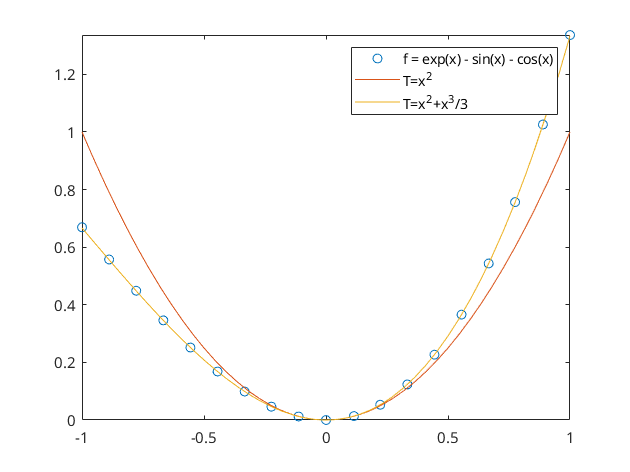

clf
fplot(f,'o');
hold on;
fplot(T3);
fplot(T6);
xlim([-1,1])
legend('f = exp(x) - sin(x) - cos(x)','T=x^2','T=x^2+x^3/3')
hold off

If we look at the above plot, we notice that there is (by eye) very good agreement between our actual function and the Taylor series approximation. We see for sufficiently small $x$, that even truncating after the second order of our Taylor series, we obtain a reasonable approximation.

For completion, the other two Taylor series in Exercise 7 have been included

**4. **When $x\approx 0$ then we have that $\sin x\approx 0$ and $e^x \approx 1$. A TS expansion here will give us an alternate form in which cancellations do not occur.

clear
syms x;
% Equation 4
f = x^-2*(sin(x)-exp(x)+1);
T1 = taylor(f,x,'Order',3)

$$T1 = -\frac{x^{2}}{24}-\frac{x}{3}-\frac{1}{2}$$

**5.** When $x\approx 0$ we have $\text{arctanh}x\approx x$. Once again, we can exploit the TS solution to give us an approximation without cancellations.

clear
syms x;
% Equation 5
f = x - atanh(x);
T3 = taylor(f,x,'Order',4)

$$T3 = -\frac{x^{3}}{3}$$